% -----------------------------------------
% HW1
% LiXin
% 2022/2/28
% -----------------------------------------

Problem 1

clear all; close all; clc;
A=[0 -1 4; 9 -14 25; -34 49 64];
B=sqrt(A.*(A>=0))+50.*(A<0)+A

B =      0    49     6
    12    36    30
    16    56    72


Problem 2

clear all; close all; clc;
deposit = 500;
year = 0;
while deposit < 10000
    deposit = deposit * 1.05;
    deposit = deposit + 500;
    year = year + 1;
end
year

year = 14

Problem 3

clear all; close all; clc;
Price=[19,18,22,21,25,19,17,21,27,29];
shares=1000;
cost=0;
receive=0;
for i = 1:10
    if Price(i) < 20
        shares=shares+100;
        cost=cost+Price(i)*100;
    elseif Price(i) > 25
        shares=shares-100;
        receive=receive+Price(i)*100;
    end
end
% a
cost

cost = 7300

% b
receive

receive = 5600

% c
shares

shares = 1200

% d
net_increase=Price(10)*shares-Price(1)*1000

net_increase = 15800

Problem 4

clear all; close all; clc;
x=[1 7 8 17 22 27];
y=[28 18 16 2 10 8];
V=[3 7 4 5 2 6];
fun=@(u)sum(0.5*sqrt((u(1)-x).^2+(u(2)-y).^2).*V);
x0=[0 0];
x_location=fminsearch(fun,x0)

x_location =     8.5237   16.0696


x_int=0;
y_int=0;
min=100000000;
for c1=0:1:30
    for c2=0:1:30
        tempt=0;
        for c3=1:1:6
            tempt=tempt+(((x(c3)-c1)^2+(y(c3)-c2)^2)^0.5)*0.5*V(c3);
        end
        if(tempt<min)
            min=tempt;
            x_int=c1;
            y_int=c2;
        end
    end
end
x_int

x_int = 9

y_int

y_int = 16

Problem 5

clear all; close all; clc;
% a
T1=70;
T2=200;
W=2;
L=2;
x=1;y=1;
n=1:2:19;
w=2/pi*2./n.*sin(n*pi*x/L).*sinh(n*pi*y/L)./sinh(n*pi*W/L);
w

w =     0.2537   -0.0038    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000


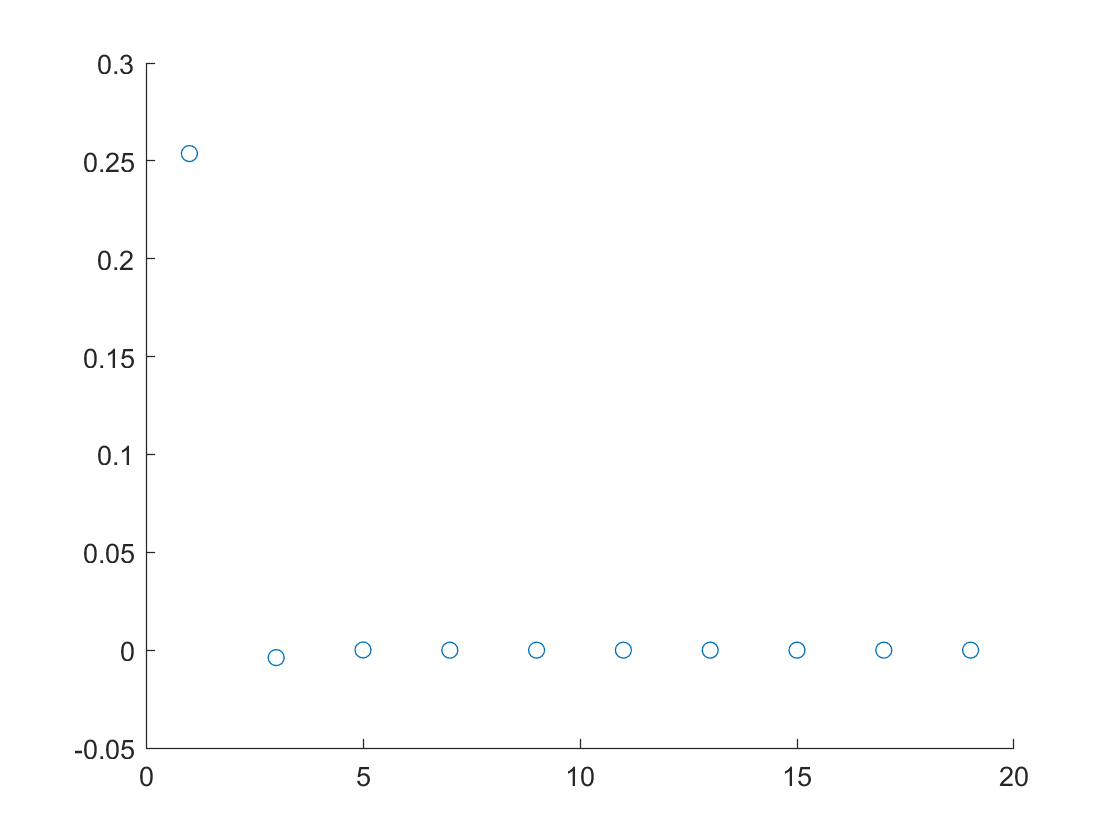

scatter(n,w)

% b
n=1;
w=0;
while true
    addend=2/pi*2/n*sin(n*pi*x/L)*sinh(n*pi*y/L)/sinh(n*pi*W/L);
    T=(T2-T1)*w+T1;
    w=w+addend;
    T_tempt = (T2-T1)*w+T1;
    if abs(T-T_tempt)/T < 0.01
        break;
    end
    n=n+2;
end
num_of_terms=(n+1)/2

num_of_terms = 2

T

T = 102.9831

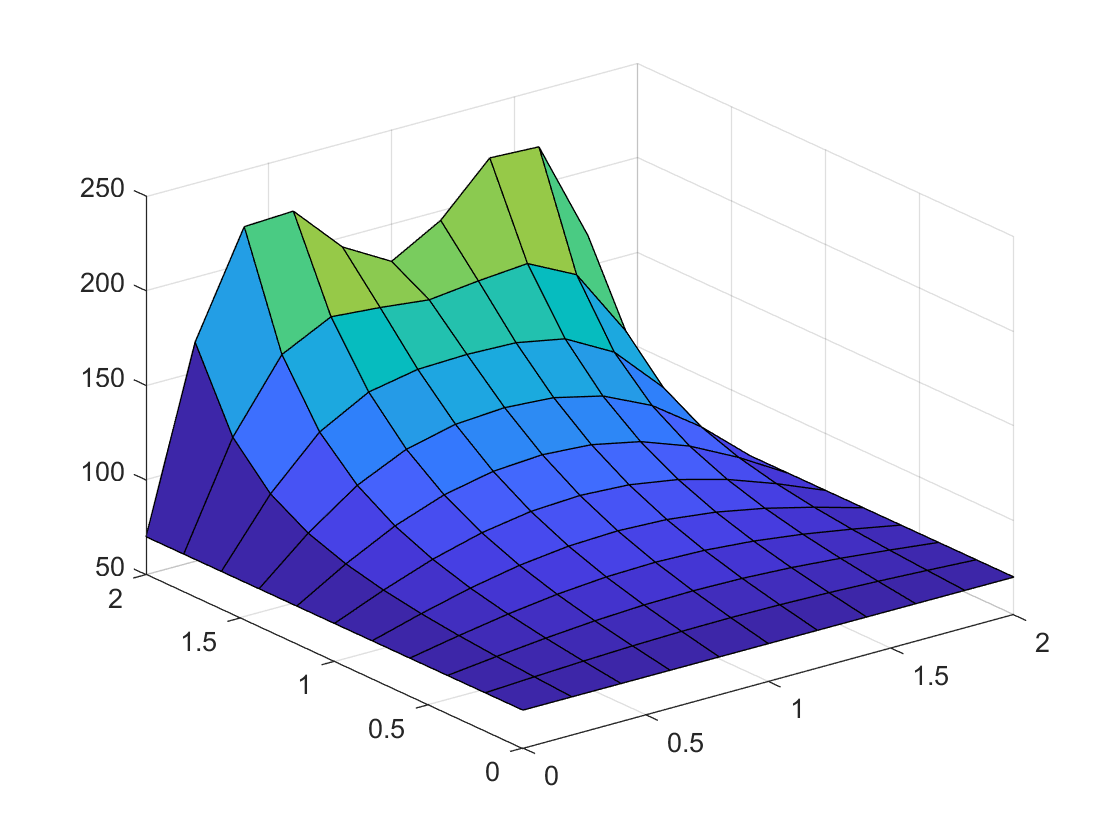

% c
x=0:0.2:2;
[X, Y]=meshgrid(x);
n=1;
w=2/pi*2./n.*sin(n*pi*X/L).*sinh(n*pi*Y/L)./sinh(n*pi*W/L);
n=3;
w=w+2/pi*2./n.*sin(n*pi*X/L).*sinh(n*pi*Y/L)./sinh(n*pi*W/L);
Z=(T2-T1)*w+T1;
surf(X,Y,Z);

Problem 6

clear all; close all; clc;
deposits=10000;
total_earned=0;
for i = 1:12
    if deposits <= 15000
        interest_rate=0.01;
    elseif deposits <= 20000
        interest_rate=0.015;
    else
        interest_rate=0.02;
    end
    earned=deposits*interest_rate;
    total_earned=total_earned+earned;
    deposits=deposits+earned;
    deposits = deposits+1000;
    fprintf('%d %.1f%% $%.2f $%.2f $%.2f\n',i,interest_rate*100,earned,deposits, ...
        total_earned);
end

1 1.0% $100.00 $11100.00 $100.00
2 1.0% $111.00 $12211.00 $211.00
3 1.0% $122.11 $13333.11 $333.11
4 1.0% $133.33 $14466.44 $466.44
5 1.0% $144.66 $15611.11 $611.11
6 1.5% $234.17 $16845.27 $845.27
7 1.5% $252.68 $18097.95 $1097.95
8 1.5% $271.47 $19369.42 $1369.42
9 1.5% $290.54 $20659.96 $1659.96
10 2.0% $413.20 $22073.16 $2073.16
11 2.0% $441.46 $23514.62 $2514.62
12 2.0% $470.29 $24984.92 $2984.92


Problem 7

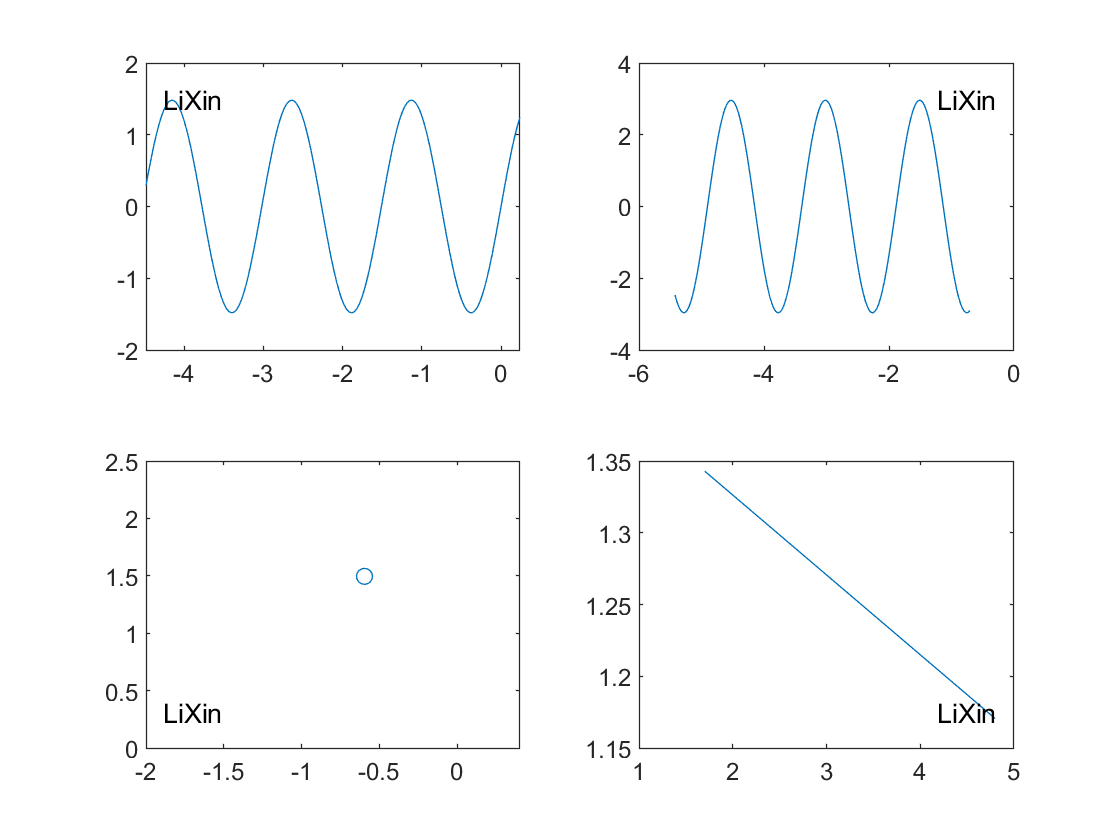

clear all; clc;

xmin = (-10) + (10-(-10)).*rand;
xrange = 2 + (5-1).*rand;
xmax=xmin+xrange;
numPts=150;
x=linspace(xmin,xmax,numPts);
x2=x-0.2*xrange;

Amp=0.5+(2-0.5).*rand;
Freq=0.5+(1.5-0.5).*rand;
y=Amp*sin(2*pi*Freq*x);
y2=2*Amp*cos(2*pi*Freq*x2);

r=2;
c=2;

subplot(r,c,1)
plot(x,y);
placeMyName(1)

subplot(r,c,2)
plot(x2,y2);
placeMyName(2)

subplot(r,c,3);
plot(-5*rand,3*rand,'o')
placeMyName(3)

subplot(r,c,4)
plot([5*rand 5*rand], [2*rand, 6*rand])
placeMyName(4)

function placeMyName(x)
    ax=gca;
    name='LiXin';
    x_interval=(ax.XLim(2)-ax.XLim(1))/8;
    y_interval=(ax.YLim(2)-ax.YLim(1))/8;
    switch x
        case 1 % upper left
            text(ax.XLim(1)+x_interval,ax.YLim(2)-y_interval,name,'HorizontalAlignment',"center")
        case 2 % upper right
            text(ax.XLim(2)-x_interval,ax.YLim(2)-y_interval,name,'HorizontalAlignment',"center")
        case 3 % lower left
            text(ax.XLim(1)+x_interval,ax.YLim(1)+y_interval,name,'HorizontalAlignment',"center")
        case 4 % lower right
            text(ax.XLim(2)-x_interval,ax.YLim(1)+y_interval,name,'HorizontalAlignment',"center")
    end
end


